# LBG quantizer on static images

Import the image

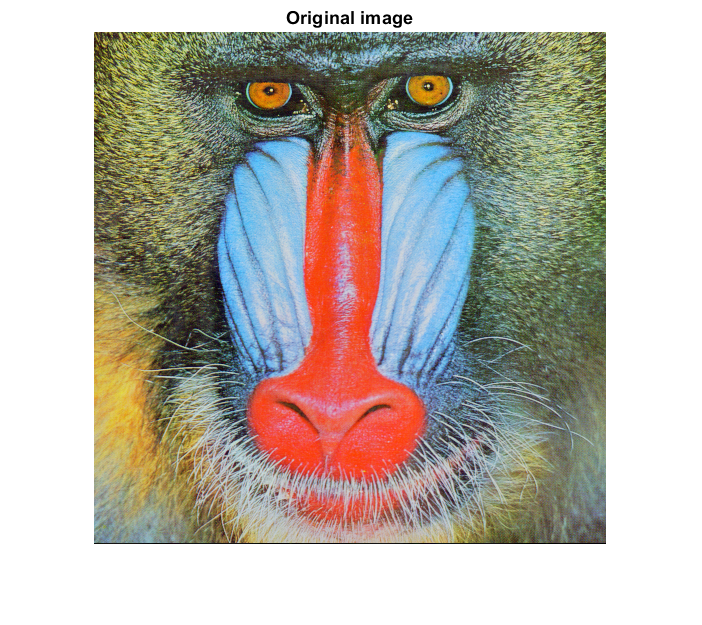

clear all

path1 = 'data\lena.tiff';
path2 = 'data\baboon.png';
path3 = 'data\peppers_red_green.png';
path4 = 'data\gradient.png';
path5 = 'peppers.png';
path6 = 'autumn.tif';
path7 = 'lighthouse.png';
path8 = 'pears.png';


A = imread(path2);
% A = imread(strcat(path, 'lena_full.jfif'));
imshow(A)
title("Original image")

Creating the Codebook with LBG algorithm and splitting technique

global X;
global M;
global std_dist; 

X = double(reshape(A, [],3))./255;
M = ones(size(X, 1),1);
std_dist = 0.5;

c0 = sum(X, 1)/length(X);
C = c0;
% test run
for i = 1:8
%     C = LBGCentroidSplit(C);
    C = LBGCentroidSplitRegular(C);
end

2 -0.00092448
3 7.4956e-05
5 5.1668e-05
7 0.00022921
8 0.00040607
15 0.00043566
12 0.00044275
21 0.00044932


% %confront kmeans
% [idx, C] = kmeans(X, 256)


% Making a codebook
Codebook = uint8(C*255);

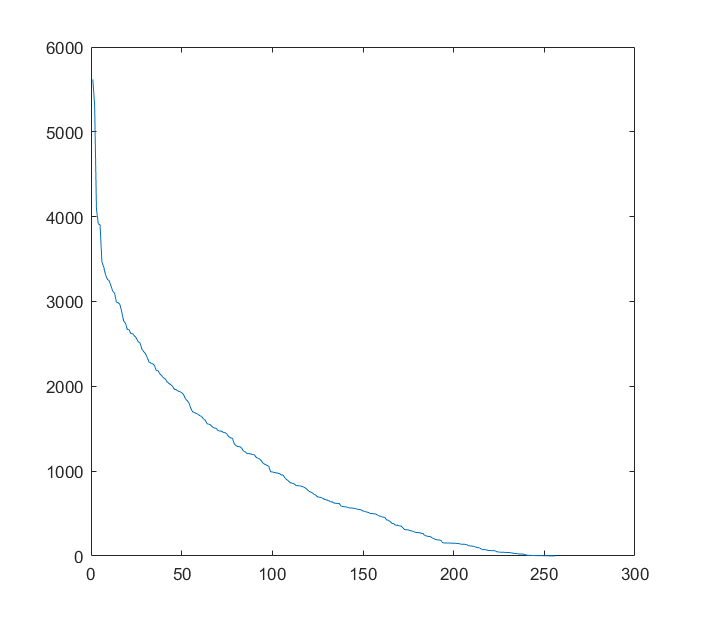


% evaluate cluster sizes
[cl_size, cl] = groupcounts(M);
[cl_size_sorted, sorting] = sort(cl_size, 'descend');

plot(cl_size_sorted)

Encoding the image

We can evaluate the space used considering we have to store 8 bit/ pixel plus the dimension of the codebook. That is 

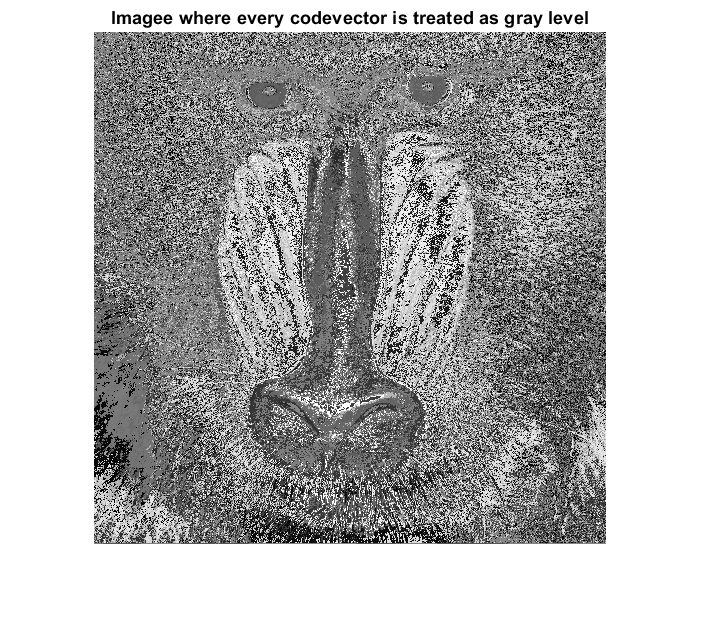

% encoding
A_r = double(reshape(A, [],3));
A_dist = pdist2(A_r, double(Codebook), "euclidean");
[~, A_enc] = min(A_dist, [], 2);
A_enc = uint8(A_enc - 1);

%reshape to original pixel size
A_enc = reshape(A_enc, size(A,1), size(A,2), 1);

imshow(A_enc)
title('Imagee where every codevector is treated as gray level')

We can evaluate the space used considering we have to store 8 bit/ pixel plus the dimension of the codebook.

enc_size = 8 * size(A_enc,1) * size(A_enc,2) + 8 * size(Codebook, 1) * size(Codebook, 2);
enc_rate = enc_size / (size(A,1)*size(A,2));
enc_gain = (8 * size(A,1) * size(A,2) * size(A,3))/enc_size;

disp(['Final bit rate per pixel considering the codebook is ', num2str(enc_rate)])

Final bit rate per pixel considering the codebook is 8.0234


disp(['Coding gain w.r.t. original image is ', num2str(enc_gain)])

Coding gain w.r.t. original image is 2.9912


Decoding the image

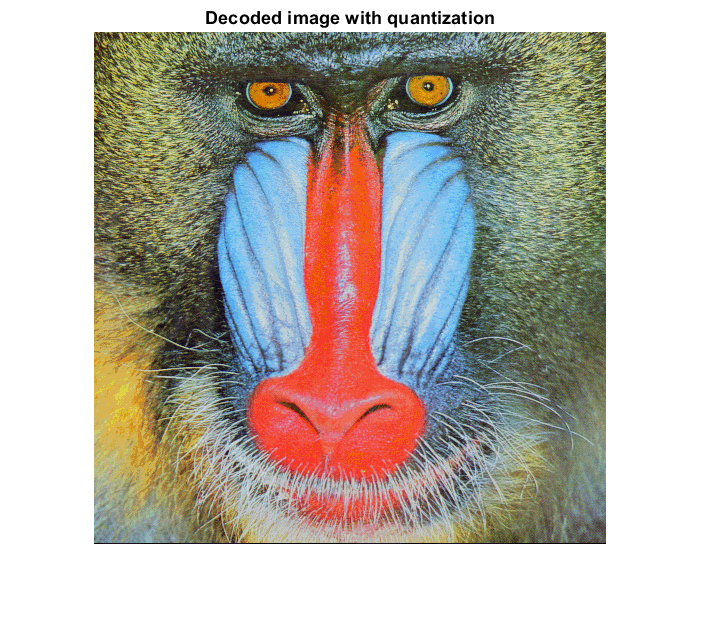

A_enc = reshape(A_enc, [], 1);

% get codevectors, but need to add 1 to the index since Matlab vectors
% start from 1
A_dec = Codebook(A_enc+1,:);
A_dec = uint8(reshape(A_dec, size(A)));

imshow(A_dec)
title("Decoded image with quantization")

Evaluate distortion

[d, dImg] = imageDistortion(A, A_dec);
disp(['Distortion is ', num2str(d)])

Distortion is 0.0024046


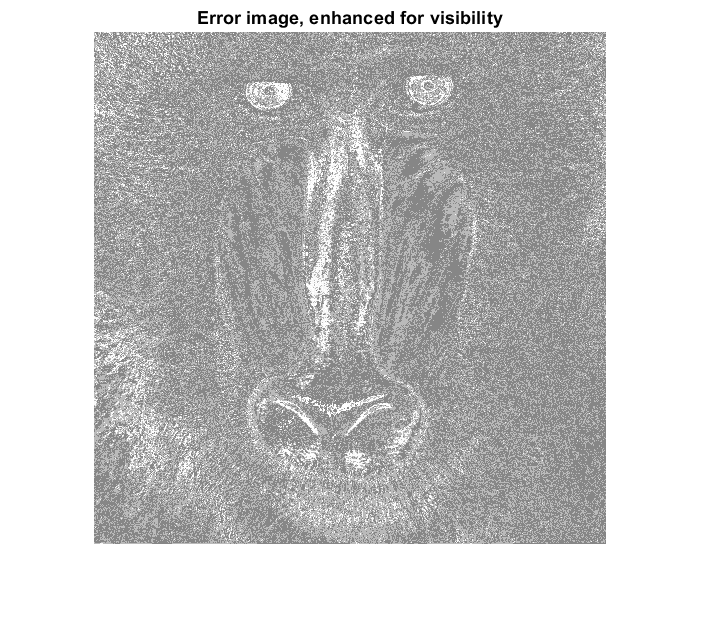

% enhance contrast for easier visualization
J = histeq(dImg);
imshow(J)
title('Error image, enhanced for visibility')

Confront with jpeg

%create a jpg copy with default implementation  
filename = "file_workspace\jpgtest.jpeg";
quality = 20;
imwrite(A, filename,"jpeg", "Quality", quality);
A_jpeg = imread(filename);

delete(filename);

[d_jpeg, ~] = imageDistortion(A,A_jpeg);
[d_lbg, ~] = imageDistortion(A, A_dec);
[d_cross, dImg_cross] = imageDistortion(A_jpeg, A_dec);
fprintf(['LBG distortion: ', num2str(d_lbg),'\njpeg distortion: ', num2str(d_jpeg), '\nLBG vs jpeg distortion: ', num2str(d_cross)])

LBG distortion: 0.0024046
jpeg distortion: 0.014812
LBG vs jpeg distortion: 0.01638

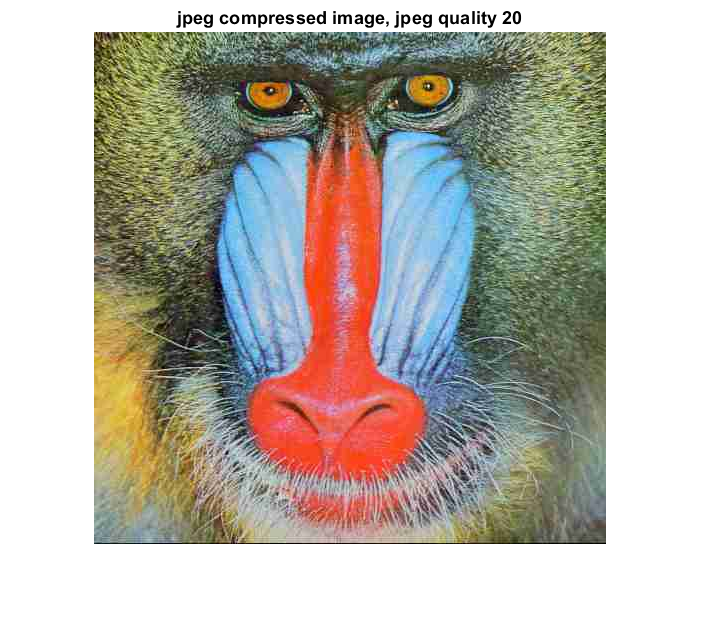

figure
imshow(A_jpeg);
title(['jpeg compressed image, jpeg quality ', num2str(quality)])

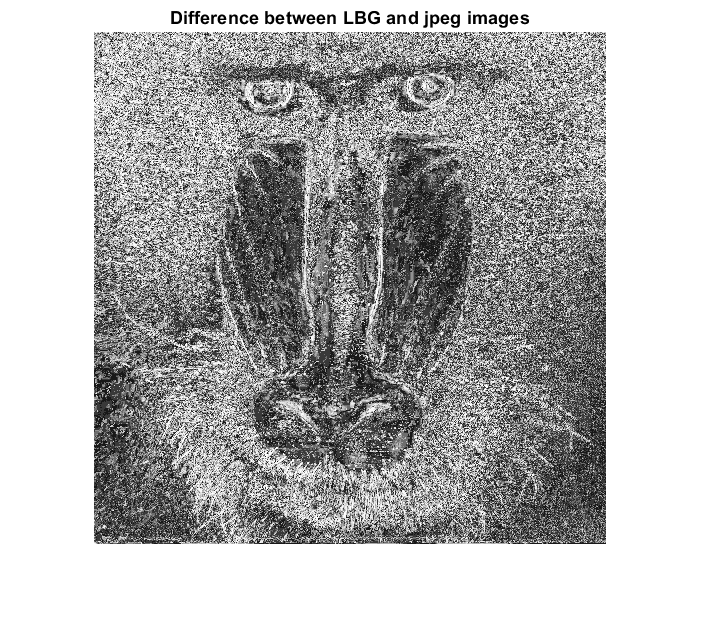

figure()
imshow(histeq(dImg_cross))
title('Difference between LBG and jpeg images')